close all
clear


rng(2019)
dataset = load('retina.mat');
patient = dataset.patient

patient =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


type = dataset.type

type = 2987×1 string array
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "cone"
    "

dataset = dataset.expr

dataset =    -0.0502    0.1812    0.9202   -0.1248    1.3036   -1.4305    0.9249   -1.3809   -0.2350    0.0126   -0.4730    0.1155   -0.0815    0.4233   -0.2359    0.2163   -0.3555    0.0246   -0.4579    0.0351   -0.5904   -0.2829   -0.0586    0.2382   -0.2894    0.1407   -0.0724    0.2083   -0.0334    0.3786   -0.5317    0.2782   -0.6884    0.2658   -0.0637    0.1242   -0.5904    0.0220   -0.3266   -0.0902    0.8814   -0.0328    0.2484    0.0719    0.1203   -0.5557    0.4095    0.0595   -0.9971   -0.1049
   -0.2272   -0.1137    0.6758   -0.0976    0.9630   -1.1650    1.2131   -1.5422   -0.1296    0.1113    0.0632    0.1854    0.0399    0.2724   -0.2327    0.1572   -0.3772   -0.2001   -0.4578   -0.0578    0.1785   -0.4603   -0.0330   -0.2740    0.0091   -0.1324    0.1815   -0.3183    0.4471   -0.2864   -0.2540    0.3294    0.0826   -0.0602   -0.1919    0.1828   -0.3787    0.4240   -0.4727    0.0148   -0.0168   -0.0485    0.2546   -0.3860   -0.2814    0.0740   -0.0094   -0.1805   -0.012

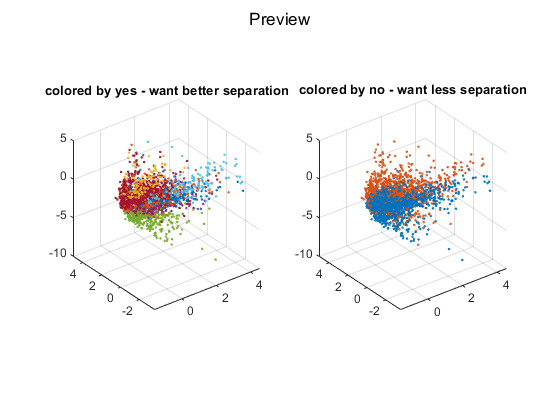


c = 2;
n = size(dataset, 1);

no = patient;
yes = type;

figure
sgtitle('Preview')
subplot(1, 2, 1)
for t = unique(type)'
    scatter3(dataset(yes == t, 1), dataset(yes == t, 2), dataset(yes == t, 3), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter3(dataset(no == 1, 1), dataset(no == 1, 2), dataset(no == 1, 3), 2)
hold on
scatter3(dataset(no == 2, 1), dataset(no == 2, 2), dataset(no == 2, 3), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')

symk = @(x) exp(-(mpdist(x) .^ 2) / (2 * 5 ^ 2)); % RBF kernel
%symk = @(x) (x * x' + 2) .^ 2;

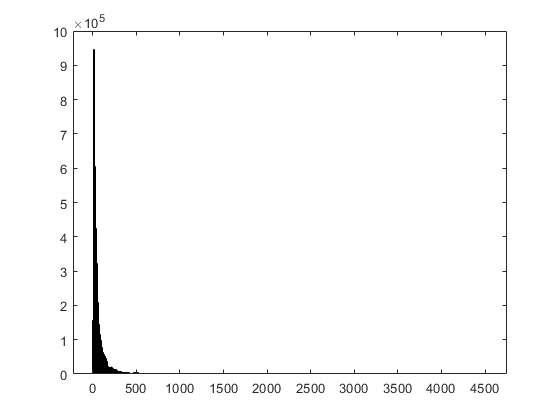

K = symk(dataset);

figure
temp = mpdist(dataset) .^ 2;
histogram(temp(:))

## AAT

top = zeros(c, 1);
bot = zeros(c, 1);
num = zeros(c, 1);
for a = 1 : c
    num(a) = sum(no == a);
    if a == 1
        top(a) = 1;
    else
        top(a) = top(a - 1) + n - num(a - 1);
    end
    bot(a) = top(a) + n - num(a) - 1;
end

AAT = zeros((c - 1) * n);
for a = 1 : c
    for b = 1 : (a - 1)
        term2 = mean(mean(K(no == a, no == b)));
        term3 = mean(K(no == a, no ~= b), 1);
        term4 = mean(K(no ~= a, no == b), 2);
        
        AAT(top(a) : bot(a), top(b) : bot(b)) = K(no ~= a, no ~= b) + term2 - term3 - term4;
        AAT(top(b) : bot(b), top(a) : bot(a)) = AAT(top(a) : bot(a), top(b) : bot(b))';
    end
    
    b = a;
    term2 = mean(mean(K(no == a, no == b)));
    term3 = mean(K(no == a, no ~= b), 1);
    term4 = mean(K(no ~= a, no == b), 2);
    
    AAT(top(a) : bot(a), top(b) : bot(b)) = K(no ~= a, no ~= b) + term2 - term3 - term4;
end

% AAT = AAT / eigs(AAT, 1);

## distances

term11 = zeros(n, c);
for a = 1 : c
    term11(:, a) = mean(K(:, no == a), 2);
end

ind1 = [];
ind2 = [];
for a = 1 : c
    ind1 = [ind1 find(no ~= a)'];
    ind2 = [ind2 (zeros(1, n - num(a)) + a)];
end

% Note: these only apply to RBF kernel
DE = sqrt(diag(K) + diag(K)' - K - K');
DEAAT = sqrt(diag(AAT)); % column vector

O = zeros(n);

for jj = 1 : n
    vec = K(jj : n, ind1) - K(jj, ind1) + term11(jj, ind2) - term11(jj : n, ind2);
    %O(jj : n, jj) = (sum((vec ./ DE(jj : n, jj) ./ DEAAT') .^ 10, 2) / (c - 1) / n) .^ (1/10);
    O(jj : n, jj) = max(abs(vec ./ (DE(jj : n, jj) + 1e-9) ./ DEAAT'), [], 2);
end

O = O + (O' .* (1 - eye(n)));

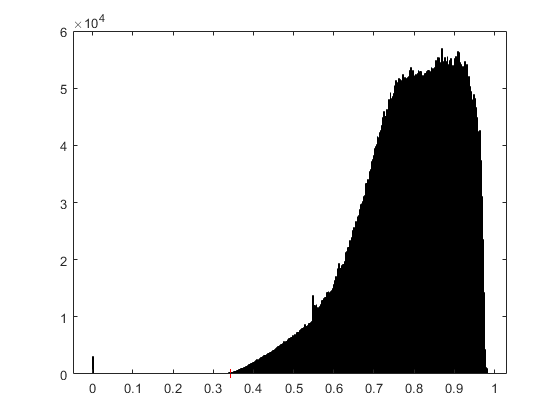

sorted = sort(O(:));
sorted = sorted(sorted > 0);
th2 = sorted(1600);

figure
histogram(O(:));
hold on
plot(th2, 0, '+r')


orth_sub1 = [];
orth_sub2 = [];
for ii = 1 : n
    for jj = 1 : (ii - 1)
        if O(ii, jj) <= th2
            orth_sub1 = [orth_sub1 ii];
            orth_sub2 = [orth_sub2 jj];
        end
    end
end

BBT = K(orth_sub1, orth_sub1) + K(orth_sub2, orth_sub2) - K(orth_sub1, orth_sub2) - K(orth_sub2, orth_sub1);

th = 1e-12;
r = min(2000, size(BBT, 1));

[u, s] = eigs(BBT, r);
s = diag(s);
mask = s / max(s) > th;
s = s(mask);
u = u(:, mask);



D = zeros(n);
for jj = 1 : n
    vec = K(jj : n, orth_sub1) - K(jj, orth_sub1) + K(jj, orth_sub2) - K(jj : n, orth_sub2);
    D(jj : n, jj) = sqrt(sum((vec * u) .^ 2 ./ sqrt(s'), 2));
end

%   ./ s'

D = D + (D' .* (1 - eye(n)));

umap_obj = umap();
umap_obj.metric = 'precomputed';
R = umap_obj.fit(D);

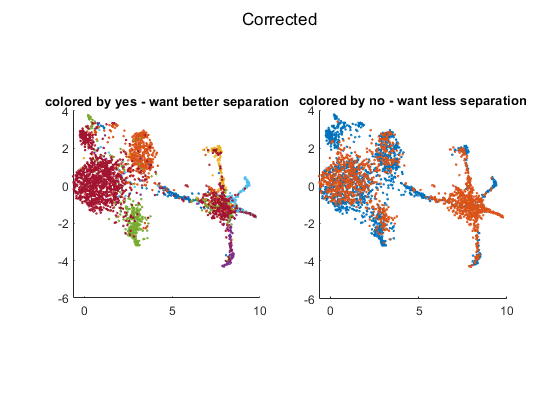

%R = tsne(D, [], 2);
%R = mdscale(D, 2);

figure
sgtitle('Corrected')
subplot(1, 2, 1)
for t = unique(type)'
    scatter(R(yes == t, 1), R(yes == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter(R(no == 1, 1), R(no == 1, 2), 2)
hold on
scatter(R(no == 2, 1), R(no == 2, 2), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')


D = zeros(n);
for jj = 1 : n
    vec = K(jj : n, orth_sub1) - K(jj, orth_sub1) + K(jj, orth_sub2) - K(jj : n, orth_sub2);
    D(jj : n, jj) = sqrt(sum((vec * u) .^ 2, 2));
end

%   ./ s'

D = D + (D' .* (1 - eye(n)));

umap_obj = umap();
umap_obj.metric = 'precomputed';
R = umap_obj.fit(D);

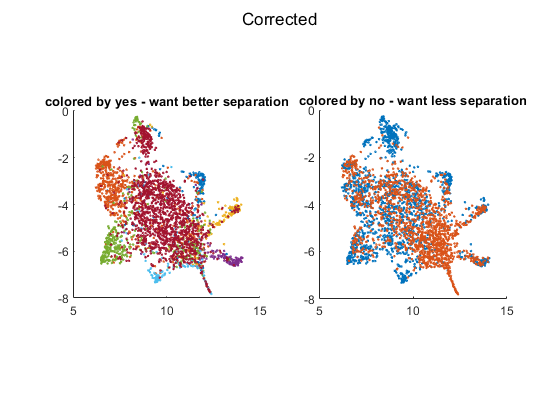

%R = tsne(D, [], 2);
%R = mdscale(D, 2);

figure
sgtitle('Corrected')
subplot(1, 2, 1)
for t = unique(type)'
    scatter(R(yes == t, 1), R(yes == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter(R(no == 1, 1), R(no == 1, 2), 2)
hold on
scatter(R(no == 2, 1), R(no == 2, 2), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')

umap_obj = umap();
R0 = umap_obj.fit(dataset);

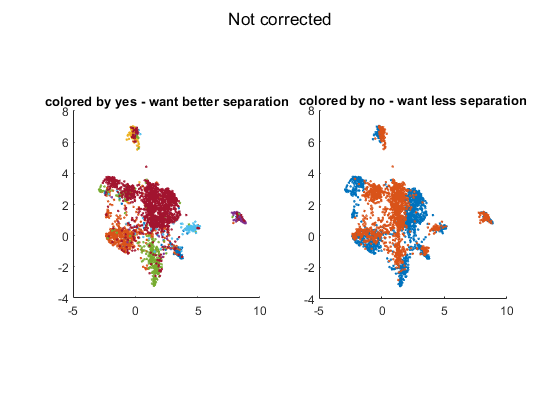

%R = tsne(D, [], 2);
%R = mdscale(D, 2);

figure
sgtitle('Not corrected')
subplot(1, 2, 1)
for t = unique(type)'
    scatter(R0(yes == t, 1), R0(yes == t, 2), 2)
    hold on
end
pbaspect([1 1 1])
title('colored by yes - want better separation')

subplot(1, 2, 2)
scatter(R0(no == 1, 1), R0(no == 1, 2), 2)
hold on
scatter(R0(no == 2, 1), R0(no == 2, 2), 2)
pbaspect([1 1 1])
title('colored by no - want less separation')